# Creación de mascara para las imagenes

Se describe el código usado que el usuario usará para definir la región de interes en el sistema de visión omnidireccional, debe definir el circulo de forma iterativa y al finalizar hacer doble clic para terminar de definir la mascara. Al final se muestra el resultado y los parametros de la máscara se guardan en una variable que se usa posteriormente.

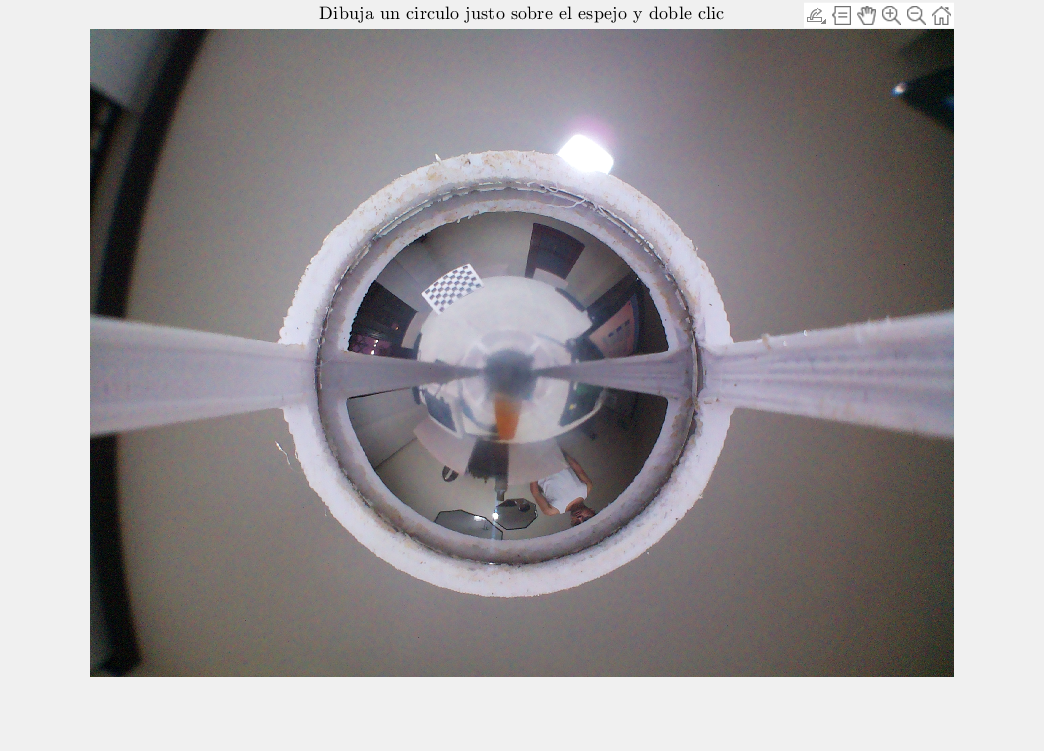

%% 1) Carga tu imagen de referencia
Iref = imread('fotos_cam/cal0.png');
figure; imshow(Iref);
title('Dibuja un circulo justo sobre el espejo y doble clic','Interpreter','latex');

%% 2) Dibuja interactivamente un círculo sobre el espejo
h = drawcircle('Color','r','LineWidth',2);  
wait(h);  % espera a que termines de ajustar y hacer doble clic para terminar

pos = h.Center;   % [x y]
rad = h.Radius;   % único radio
delete(h);        % quita el objeto interactivo

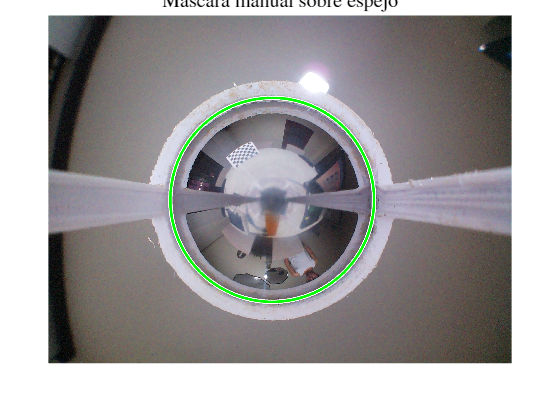


%% 3) Construye la máscara a partir de los parámetros
[H,W,~] = size(Iref);
[x,y] = meshgrid(1:W,1:H);
mask_ref = (x - pos(1)).^2 + (y - pos(2)).^2 <= rad.^2;

%% 4) Muestra la máscara superpuesta para verificar
figure; imshow(Iref); hold on;
visboundaries(mask_ref,'Color','g','LineWidth',1.5);
title('Mascara manual sobre espejo','Interpreter','latex');

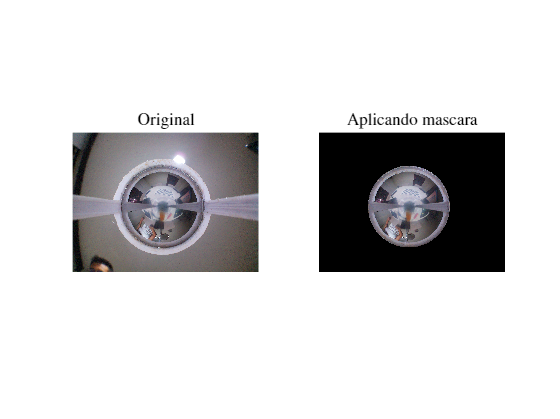


%% 5) Guarda la máscara para reutilizar luego
save('espejo_mask.mat','mask_ref');

%% 6) Ejemplo de aplicación a otra imagen
I = imread('fotos_cam/cal1.png');    % otra foto distinta
Iseg = I;
for c = 1:3
    tmp = I(:,:,c);
    tmp(~mask_ref) = 0;
    Iseg(:,:,c) = tmp;
end

figure(); 
subplot(1,2,1), imshow(I),   title('Original','Interpreter','latex');
subplot(1,2,2), imshow(Iseg), title('Aplicando mascara','Interpreter','latex');